# RoadRunner - Simulinkのcosimulationによるセンサモデルの活用

## 変数、RoadRunnerをクリーンアップ

if exist("rrApp", "var")
    if class(rrApp) == "roadrunner"
        rrApp.close();
    end
end
if exist("rrSim", "var")
    delete(rrSim);
end
close all;
clear;

% Japanese: このフラグがTrueの場合、正解が書かれたコードをそのまま実行するソリューションモードを有効にします。
isSolutionMode = true

isSolutionMode = logical
   1


## RoadRunnerをMATLABから起動する

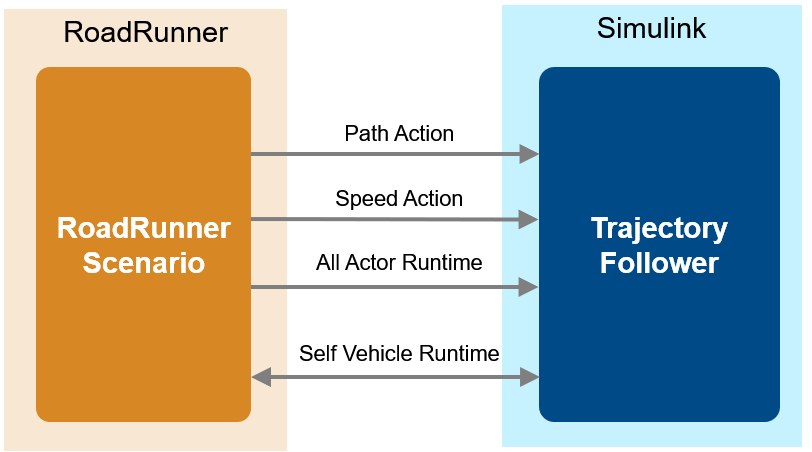

% R2024a以前のversionで実施する場合は、次のコマンドで例題を開き、そちらを実行ください
% openExample('driving/AddSensorsToRoadRunnerScenarioUsingSimulinkExample')
rrApp = roadrunner();
rrProjectPath = rrApp.status.Project.Filename;
copyfile("RRfiles/TrajectoryCutInWithVariables.rrscenario",fullfile(rrProjectPath,"Scenarios/"));

% シナリオを起動　シーンはシナリオと紐づいているため、自動でシーンも開く
rrApp.openScenario("TrajectoryCutInWithVariables");

% RoadRunnerとSimulinkの実行ステップサイズを揃える
simStepSize = 0.1;
rrSim = rrApp.createSimulation();

Connection status: 1
Connected to RoadRunner Scenario server on localhost:60730, with client id {df9fdc4c-97a9-4c3e-8d5f-0540e9343143}


setRRSCameraMode(rrApp, "follow", actorID=2);
rrSim.set("StepSize", simStepSize);

% RoadRunnerの情報をSimulinkで取得するため、Busオブジェクトを定義
% To support Reader and Writer blocks, some bus objects must be loaded
loadRoadRunnerBusObject();
load("busDefinitionsForRRSim.mat"); % sensor simulation用のバスオブジェクトを読出し

% 車両の位置変更定数
gainArg = [
    1 0 0 0.5;
    0 1 0 0.1;
    0 0 1 0;
    0 0 0 1];

% Simulinkのモデルを開く
model_name = 'SimulinkVehicle.slx';
open_system(model_name);

## RoadRunner Scenarioで活用可能なセンサブロック

LiDAR、ミリ波レーダ、カメラの3つのセンサブロックを用意。[RoadRunner Scenario Reader](https://jp.mathworks.com/help/driving/ref/roadrunnerscenarioreader.html)ブロックより真値のアクターやレーン情報を入力し、画角、検知距離の考慮やセンサ特有の誤差を付与するセンサモデル。

- LiDARセンサ：[Lidar Point Cloud Generator](https://jp.mathworks.com/help/driving/ref/lidarpointcloudgenerator.html) or [Lidar Sensor](https://jp.mathworks.com/help/lidar/ref/lidarsensor.html) (天候の影響や自車移動による点群の歪みを考慮可能。Lidar Toolboxが必要。)

- ミリ波レーダ：[Driving Radar Data Generator](https://jp.mathworks.com/help/driving/ref/drivingradardatagenerator.html)

- カメラ：[Vision Detection Generator](https://jp.mathworks.com/help/driving/ref/visiondetectiongenerator.html)

RoadRunner Scenario ReaderブロックのTopic CategoryはSensorに設定し、それぞれのSensor IDを対応して設定する。

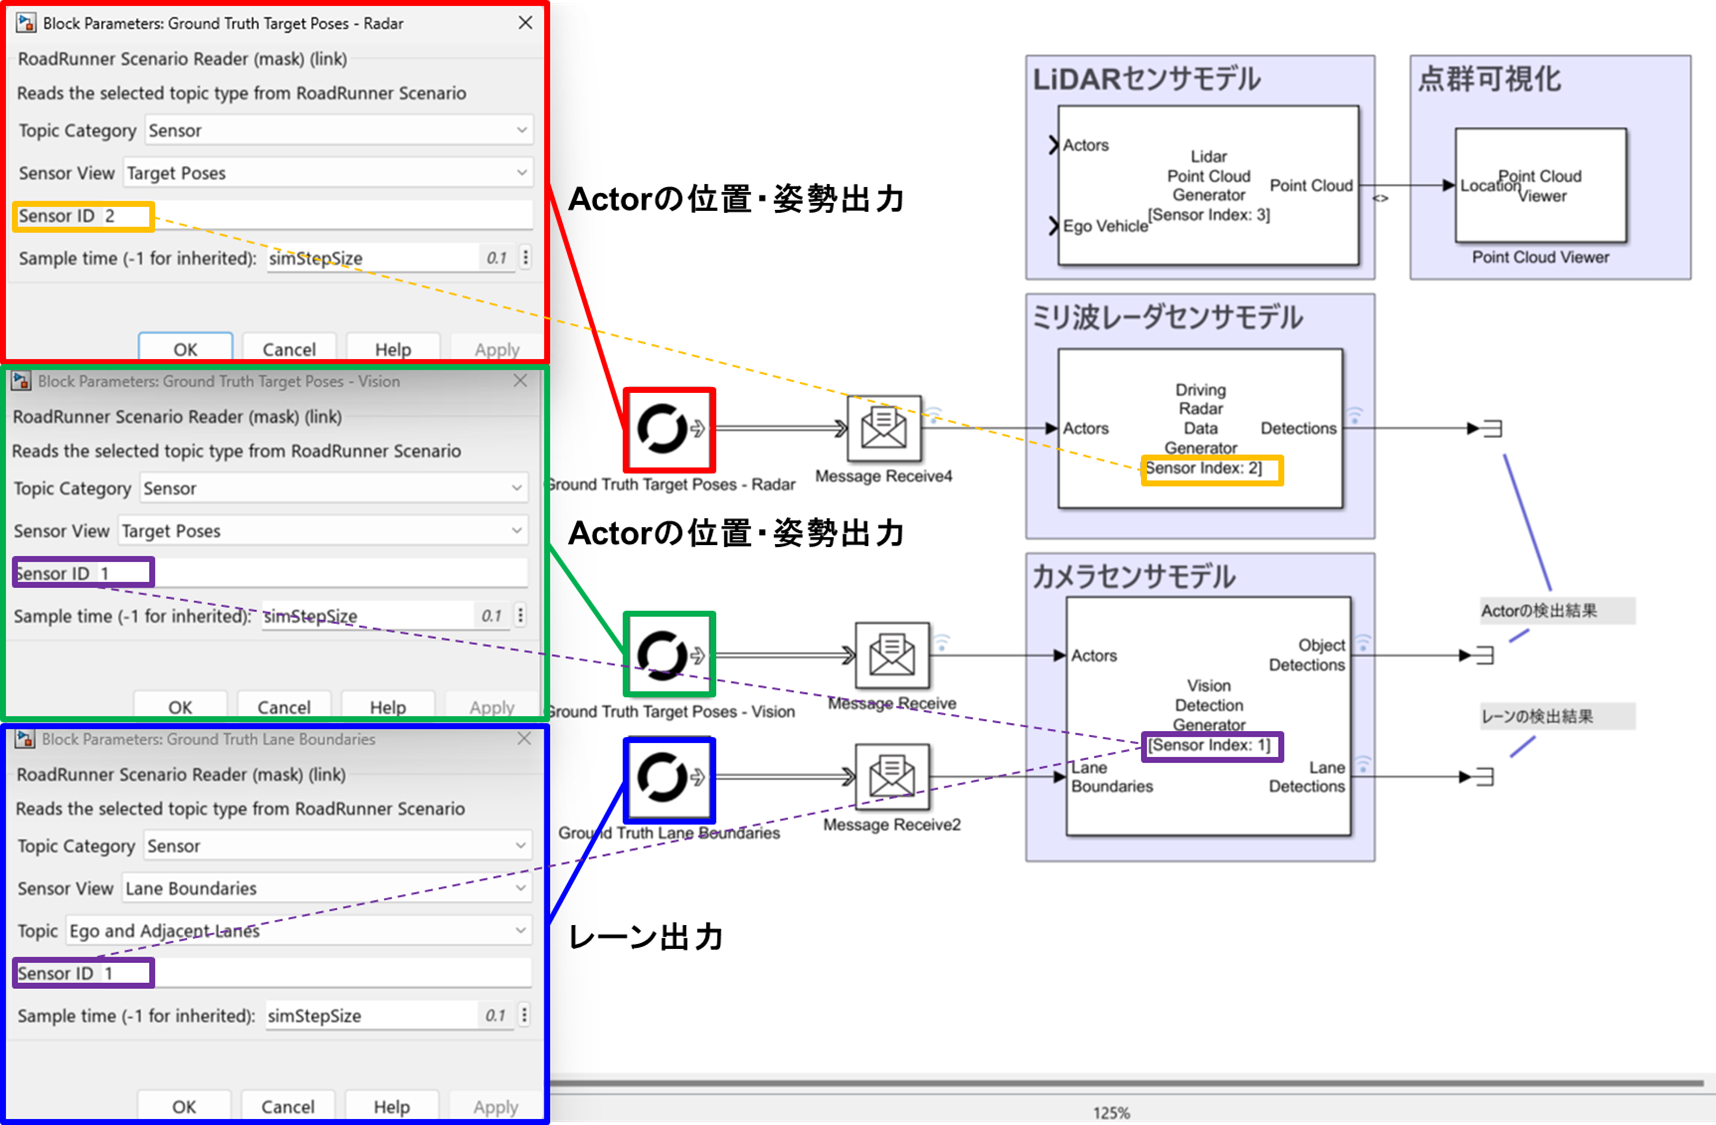

## センサ出力確認方法

センサブロックの出力はBird's-Eye Scopeで確認可能。LiDARセンサはPoint Cloud Viewerブロックにより3次元的に点群を可視化可能。

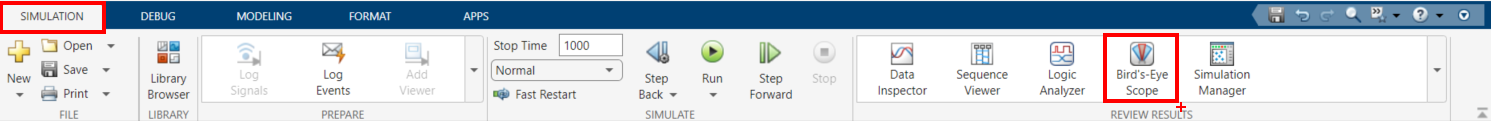

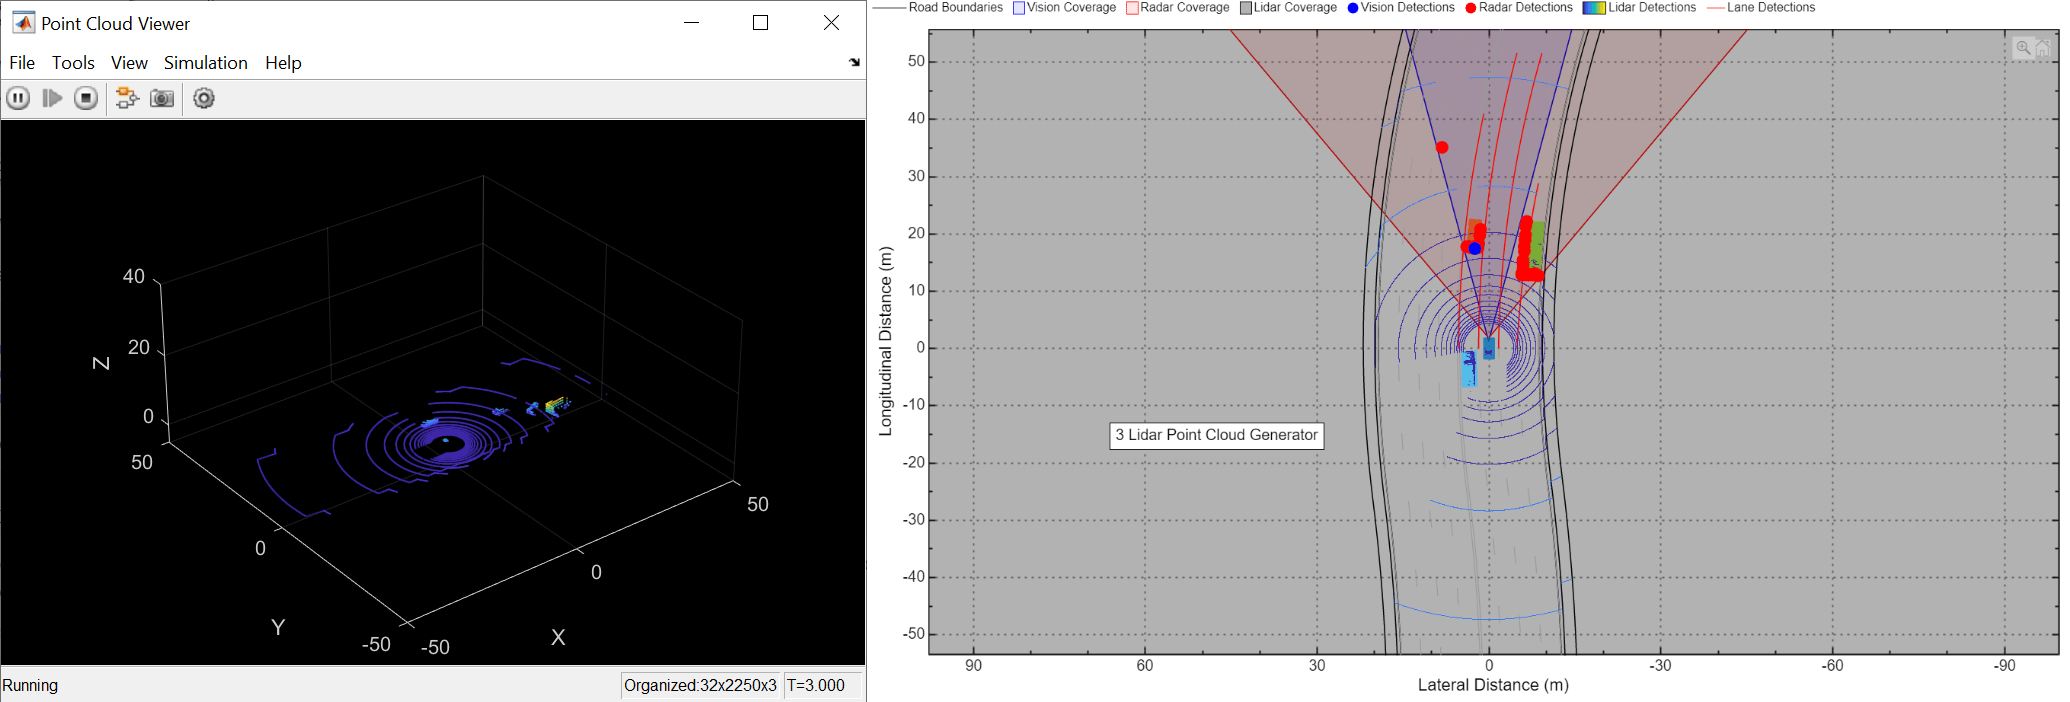

## LiDARセンサを追加し、RoadRunnerを実行する

Lidar Point Cloud GeneratorとPoint Cloud Viewerを追加

白い車両はActor IDが２のため、LiDAR Point Cloud Generatorの ActorID of ego vehicleは２を設定

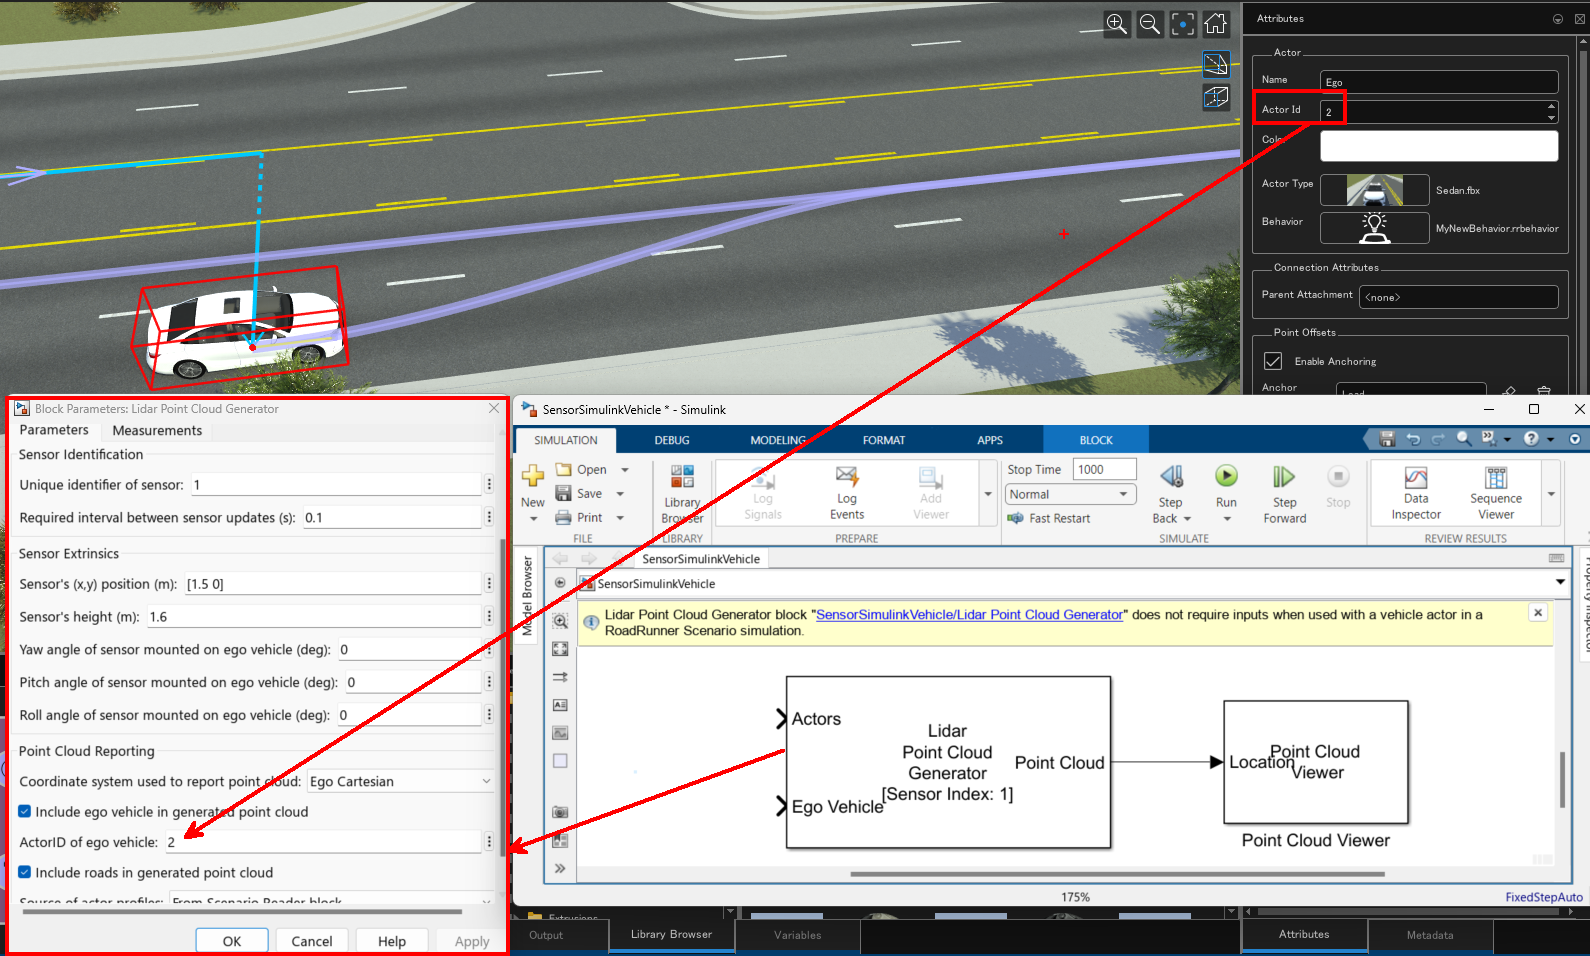

if isSolutionMode
    % Simulinkのモデルを開く
    model_name = 'SensorSimulinkVehicle.slx';
    open_system(model_name);
    % 上記は既にLiDARセンサを追加したモデル　使用する場合はBehaviorファイルの参照先を書き換えること
    % (SimulinkVehicle.slx->SensorSimulinkVehicle.slx)

    copyfile("RRfiles/MyLidarSensorSimulation.rrbehavior.rrmeta",fullfile(rrProjectPath,"Assets/Behaviors/"));
    rrApp.setScenarioVariable("EgoBehavior", "<PROJECT>/Assets/Behaviors/MyLidarSensorSimulation.rrbehavior");
end

% Simulationを開始する
set(rrSim,"SimulationCommand","Start");
% RoadRunner ScenarioのSimulation実行が終了するまで待機
while strcmp(get(rrSim,"SimulationStatus"),"Running")
    pause(1);
end

## 発展：カメラやミリ波レーダモデルを追加し、実行する

Bird's-eye Scopeでカメラ、ミリ波の検出点を確認する場合、Simulinkのモデル設定でSignal loggingを有効にする必要あり

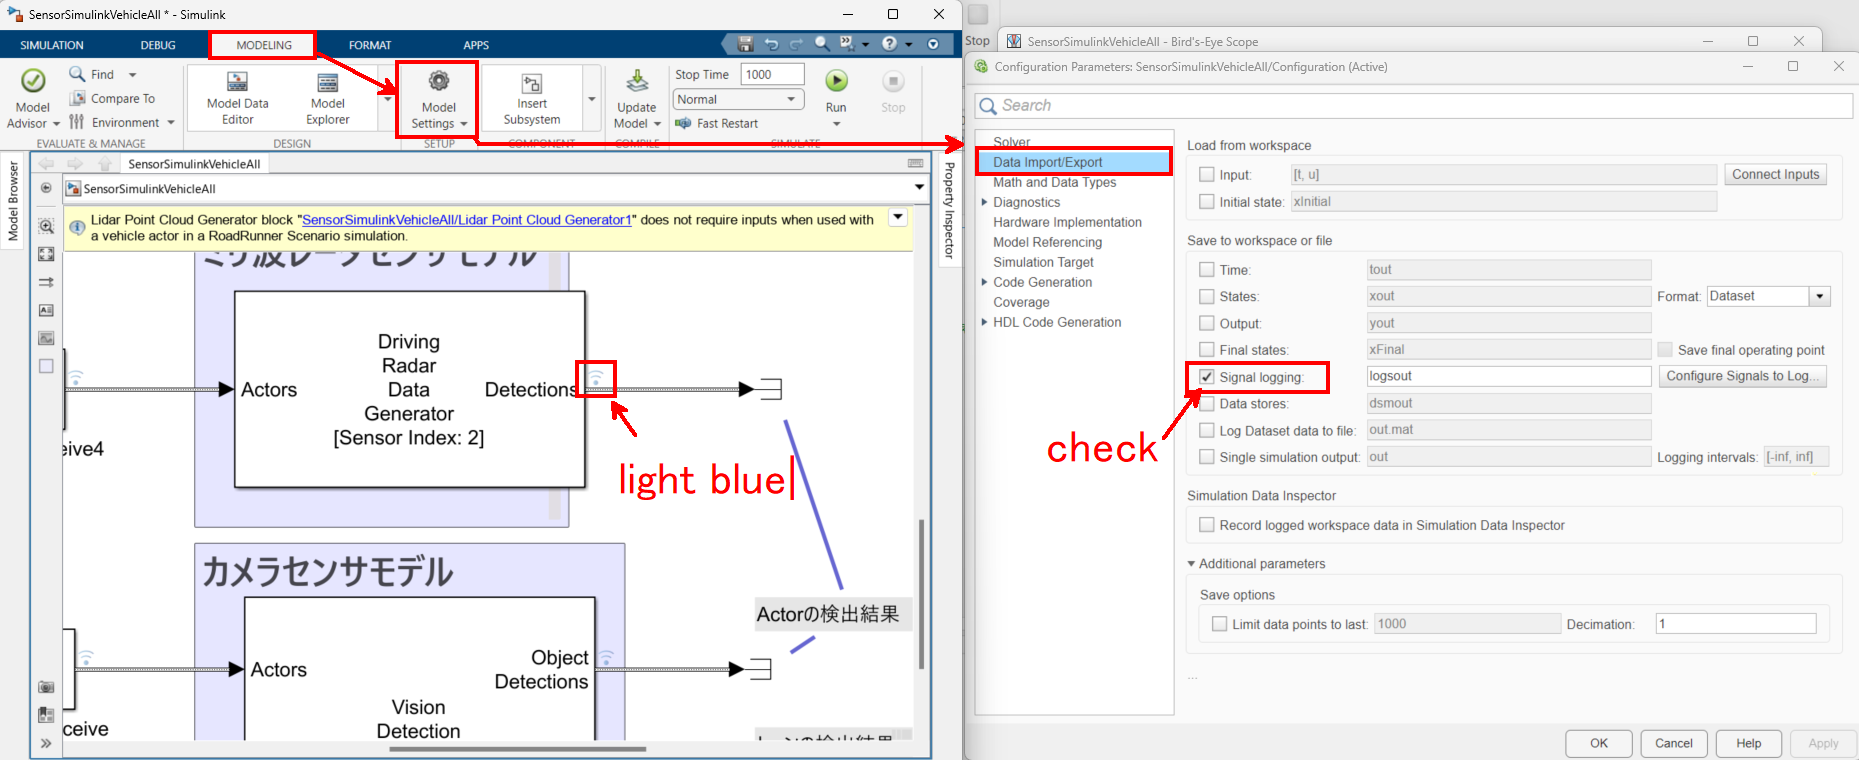

下記手順でBEV Scopeを有効にする

- Signal loggingを有効にする

- RoadRunner ScenarioとSimulinkを一度実行する

- BEV Scopeを開き、Find Singalsをクリック（毎実行前にFind Signalsを押して更新してください）

- 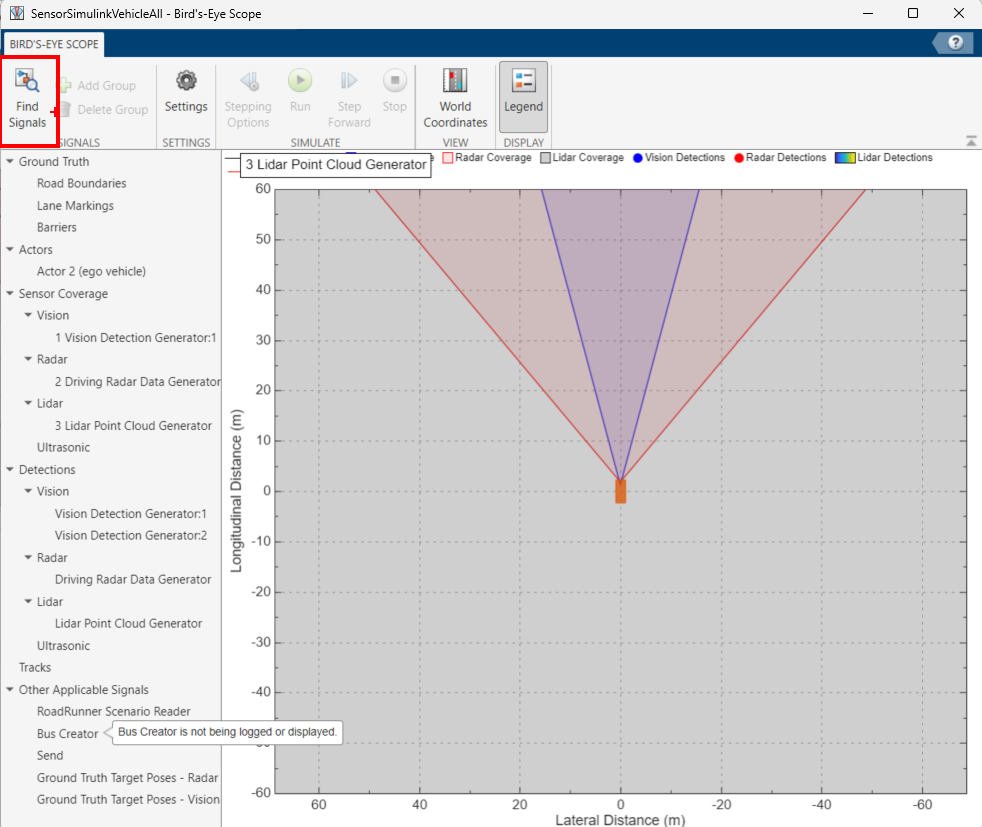

if isSolutionMode
    % Simulinkのモデルを開く
    model_name = 'SensorSimulinkVehicleAll.slx';
    open_system(model_name);
    % 上記は既にLiDARセンサを追加したモデル　使用する場合はBehaviorファイルの参照先を書き換えること
    % (SimulinkVehicle.slx->SensorSimulinkVehicle.slx)

    copyfile("RRfiles/MyAllSensorSimulation.rrbehavior.rrmeta",fullfile(rrProjectPath,"Assets/Behaviors/"));
    rrApp.setScenarioVariable("EgoBehavior", "<PROJECT>/Assets/Behaviors/MyAllSensorSimulation.rrbehavior.rrmeta");
    % The above is a model with a LiDAR sensor already added. If you want to use it, change the reference of the Behavior file.
    % (SimulinkVehicle.slx->SensorSimulinkVehicle.slx)
end% 
% model_name = 'SensorSimulinkVehicleAll.slx';
% open_system(model_name);


if exist("rrSim", "var")
    if class(rrSim) == "Simulink.ScenarioSimulation"
        delete(rrSim);
    end
end

SimClient is shutdown and event thread is stopped!


rrSim = rrApp.createSimulation();
rrSim.set("StepSize", simStepSize);

% Simulationを開始する
set(rrSim,"SimulationCommand","Start");
% RoadRunner ScenarioのSimulation実行が終了するまで待機
while strcmp(get(rrSim,"SimulationStatus"),"Running")
    pause(1);
end